clear
syms Rl R Ron Rd
syms L C_out
syms il vc vg vd
syms u v
A_1=[-(Rl+Ron)/L 0;0 -1/R/C_out]

$$A\_1 = \left(\begin{array}{cc} -\frac{\mathrm{Rl}+\mathrm{Ron}}{L} & 0\\ 0 & -\frac{1}{C_{\mathrm{out}}\,R} \end{array}\right)$$

A_2=[-(Rl+Rd)/L -1/L;1/C_out -1/R/C_out]

$$A\_2 = \left(\begin{array}{cc} -\frac{\mathrm{Rd}+\mathrm{Rl}}{L} & -\frac{1}{L}\\ \frac{1}{C_{\mathrm{out}}} & -\frac{1}{C_{\mathrm{out}}\,R} \end{array}\right)$$


B_1=[1/L 0;0 0]

$$B\_1 = \left(\begin{array}{cc} \frac{1}{L} & 0\\ 0 & 0 \end{array}\right)$$

B_2=[1/L -1/L;0 0]

$$B\_2 = \left(\begin{array}{cc} \frac{1}{L} & -\frac{1}{L}\\ 0 & 0 \end{array}\right)$$


x=[il;vc]

$$x = \left(\begin{array}{c} \mathrm{il}\\ \mathrm{vc} \end{array}\right)$$

v_f=[vg;vd]

$$v\_f = \left(\begin{array}{c} \mathrm{vg}\\ \mathrm{vd} \end{array}\right)$$

syms x1 x2
f_x=A_2*x+B_2*v_f

$$f\_x = \left(\begin{array}{c} \frac{\mathrm{vg}}{L}-\frac{\mathrm{vd}}{L}-\frac{\mathrm{vc}}{L}-\frac{\mathrm{il}\,\left(\mathrm{Rd}+\mathrm{Rl}\right)}{L}\\ \frac{\mathrm{il}}{C_{\mathrm{out}}}-\frac{\mathrm{vc}}{C_{\mathrm{out}}\,R} \end{array}\right)$$

fx=subs(f_x,[il vc],[x1 x2])

$$fx = \left(\begin{array}{c} \frac{\mathrm{vg}}{L}-\frac{\mathrm{vd}}{L}-\frac{x_{2}}{L}-\frac{x_{1}\,\left(\mathrm{Rd}+\mathrm{Rl}\right)}{L}\\ \frac{x_{1}}{C_{\mathrm{out}}}-\frac{x_{2}}{C_{\mathrm{out}}\,R} \end{array}\right)$$

g_x=(A_1-A_2)*x + (B_1-B_2)*v_f

$$g\_x = \left(\begin{array}{c} \mathrm{il}\,\left(\frac{\mathrm{Rd}+\mathrm{Rl}}{L}-\frac{\mathrm{Rl}+\mathrm{Ron}}{L}\right)+\frac{\mathrm{vc}}{L}+\frac{\mathrm{vd}}{L}\\ -\frac{\mathrm{il}}{C_{\mathrm{out}}} \end{array}\right)$$


x_dot=f_x+g_x*u

$$x\_dot = \left(\begin{array}{c} u\,\left(\mathrm{il}\,\left(\frac{\mathrm{Rd}+\mathrm{Rl}}{L}-\frac{\mathrm{Rl}+\mathrm{Ron}}{L}\right)+\frac{\mathrm{vc}}{L}+\frac{\mathrm{vd}}{L}\right)-\frac{\mathrm{vc}}{L}-\frac{\mathrm{vd}}{L}+\frac{\mathrm{vg}}{L}-\frac{\mathrm{il}\,\left(\mathrm{Rd}+\mathrm{Rl}\right)}{L}\\ \frac{\mathrm{il}}{C_{\mathrm{out}}}-\frac{\mathrm{vc}}{C_{\mathrm{out}}\,R}-\frac{\mathrm{il}\,u}{C_{\mathrm{out}}} \end{array}\right)$$

x_dot=subs(x_dot,il,x1) 

$$x\_dot = \left(\begin{array}{c} \frac{\mathrm{vg}}{L}-\frac{\mathrm{vd}}{L}-\frac{\mathrm{vc}}{L}+u\,\left(x_{1}\,\left(\frac{\mathrm{Rd}+\mathrm{Rl}}{L}-\frac{\mathrm{Rl}+\mathrm{Ron}}{L}\right)+\frac{\mathrm{vc}}{L}+\frac{\mathrm{vd}}{L}\right)-\frac{x_{1}\,\left(\mathrm{Rd}+\mathrm{Rl}\right)}{L}\\ \frac{x_{1}}{C_{\mathrm{out}}}-\frac{\mathrm{vc}}{C_{\mathrm{out}}\,R}-\frac{u\,x_{1}}{C_{\mathrm{out}}} \end{array}\right)$$

x_dot=subs(x_dot,vc,x2)

$$x\_dot = \left(\begin{array}{c} \frac{\mathrm{vg}}{L}-\frac{\mathrm{vd}}{L}-\frac{x_{2}}{L}+u\,\left(x_{1}\,\left(\frac{\mathrm{Rd}+\mathrm{Rl}}{L}-\frac{\mathrm{Rl}+\mathrm{Ron}}{L}\right)+\frac{\mathrm{vd}}{L}+\frac{x_{2}}{L}\right)-\frac{x_{1}\,\left(\mathrm{Rd}+\mathrm{Rl}\right)}{L}\\ \frac{x_{1}}{C_{\mathrm{out}}}-\frac{x_{2}}{C_{\mathrm{out}}\,R}-\frac{u\,x_{1}}{C_{\mathrm{out}}} \end{array}\right)$$

x_dot=simplify(x_dot)

$$x\_dot = \left(\begin{array}{c} -\frac{\mathrm{vd}-\mathrm{vg}+x_{2}+\mathrm{Rd}\,x_{1}+\mathrm{Rl}\,x_{1}-u\,\mathrm{vd}-u\,x_{2}-\mathrm{Rd}\,u\,x_{1}+\mathrm{Ron}\,u\,x_{1}}{L}\\ -\frac{x_{2}-R\,x_{1}+R\,u\,x_{1}}{C_{\mathrm{out}}\,R} \end{array}\right)$$

x_dot=collect(x_dot,[u x1])

$$x\_dot = \left(\begin{array}{c} \frac{\mathrm{Rd}-\mathrm{Ron}}{L}\,u\,x_{1}+\frac{\mathrm{vd}+x_{2}}{L}\,u+\left(-\frac{\mathrm{Rd}+\mathrm{Rl}}{L}\right)\,x_{1}-\frac{\mathrm{vd}-\mathrm{vg}+x_{2}}{L}\\ \left(-\frac{1}{C_{\mathrm{out}}}\right)\,u\,x_{1}+\frac{x_{1}}{C_{\mathrm{out}}}-\frac{x_{2}}{C_{\mathrm{out}}\,R} \end{array}\right)$$


x1_dot=simplify(x_dot(1))

$$x1\_dot = \frac{\mathrm{Rd}-\mathrm{Ron}}{L}\,u\,x_{1}+\frac{\mathrm{vd}+x_{2}}{L}\,u+\left(-\frac{\mathrm{Rd}+\mathrm{Rl}}{L}\right)\,x_{1}-\frac{\mathrm{vd}-\mathrm{vg}+x_{2}}{L}$$


y=x1;
ydot=x_dot(2);


g=(ydot - subs(ydot,u,0))/u

$$g = -\frac{x_{1}}{C_{\mathrm{out}}}$$

f=ydot-u*g

$$f = \frac{x_{1}}{C_{\mathrm{out}}}-\frac{x_{2}}{C_{\mathrm{out}}\,R}$$


upr=1/g*(-f+v)

$$upr = -\frac{C_{\mathrm{out}}\,\left(v-\frac{x_{1}}{C_{\mathrm{out}}}+\frac{x_{2}}{C_{\mathrm{out}}\,R}\right)}{x_{1}}$$


%racunanje funkcije upravljanja upr_Block
C_out=200e-6;
R=24

R = 24

upr = eval(upr);
upr_f = matlabFunction(upr)

upr_f = function_handle with value:
    @(v,x1,x2)-(v./5.0e+3-x1+x2./2.4e+1)./x1


f =eval(f);
f_f = matlabFunction(f)

f_f = function_handle with value:
    @(x1,x2)x1.*5.0e+3-x2.*(6.25e+2./3.0)



g =eval(g);
g_f = matlabFunction(g)

g_f = function_handle with value:
    @(x1)x1.*-5.0e+3



z1 = eval(ydot)

$$z1 = 5000\,x_{1}-\frac{625\,x_{2}}{3}-5000\,u\,x_{1}$$

z1_f = matlabFunction(z1)

z1_f = function_handle with value:
    @(u,x1,x2)x1.*5.0e+3-x2.*(6.25e+2./3.0)-u.*x1.*5.0e+3


L=300e-6;   % H
vd=0.7;     % V
Rd=0.6;     % Ohm
Rl=0.1;     % Ohm
C=200e-6;   % F
Ron=0.2;      % Ohm
vg=12

vg = 12

x2e=24;%Dozvoljene vrednosti x1(300,338.9) 
x10=10;
x20=4;
ref_V=24;
sum=0;
poremecaj=1;
promena_ref=1;
sigma=0.01;
%jednacine ya racunanje stacionarnih vrednosti
syms x2 x1 u
eq=[((Rd - Ron)/L)*u*x1 + ((vd + x2)/L)*u + (-(Rd + Rl)/L)*x1 - (vd - vg + x2)/L ...
    ,x1/C-x2/R/C+(-x1)/C*u];
rez=solve(eq,[x1 u]);
x1e=rez.x1;
x1e=subs(x1e,x2,x2e);
x1e=eval(x1e)

x1e =     2.2616
   36.4051


ue=rez.u;
ue=subs(ue,x2,x2e);
ue=eval(ue)%u(0,0.05)

ue =     0.5578
    0.9725


x10=1.5;




%Generisanje PID (ne moze samo PI jer bi imao gresku stacionarnog stanja)
syms Kp Kd Ki s wf
PID=collect(Kp+Ki/s+Kd*wf/(s+wf),s)

$$PID = \frac{\mathrm{Kp}\,s^{2}+\left(\mathrm{Ki}+\mathrm{Kd}\,\mathrm{wf}+\mathrm{Kp}\,\mathrm{wf}\right)\,s+\mathrm{Ki}\,\mathrm{wf}}{s^{2}+\mathrm{wf}\,s}$$

Ob=1/s

$$Ob = \frac{1}{s}$$

W=PID*Ob

$$W = \frac{\mathrm{Kp}\,s^{2}+\left(\mathrm{Ki}+\mathrm{Kd}\,\mathrm{wf}+\mathrm{Kp}\,\mathrm{wf}\right)\,s+\mathrm{Ki}\,\mathrm{wf}}{s\,\left(s^{2}+\mathrm{wf}\,s\right)}$$

g=simplify(W/(1+W))

$$g = \frac{\mathrm{Ki}\,s+\mathrm{Ki}\,\mathrm{wf}+\mathrm{Kp}\,s^{2}+\mathrm{Kd}\,s\,\mathrm{wf}+\mathrm{Kp}\,s\,\mathrm{wf}}{\mathrm{Ki}\,s+\mathrm{Ki}\,\mathrm{wf}+\mathrm{Kp}\,s^{2}+s^{2}\,\mathrm{wf}+s^{3}+\mathrm{Kd}\,s\,\mathrm{wf}+\mathrm{Kp}\,s\,\mathrm{wf}}$$

g=collect(g,s)

$$g = \frac{\mathrm{Kp}\,s^{2}+\left(\mathrm{Ki}+\mathrm{Kd}\,\mathrm{wf}+\mathrm{Kp}\,\mathrm{wf}\right)\,s+\mathrm{Ki}\,\mathrm{wf}}{s^{3}+\left(\mathrm{Kp}+\mathrm{wf}\right)\,s^{2}+\left(\mathrm{Ki}+\mathrm{Kd}\,\mathrm{wf}+\mathrm{Kp}\,\mathrm{wf}\right)\,s+\mathrm{Ki}\,\mathrm{wf}}$$

zel=(s+1400)^3 % 10 Hz

$$zel = {\left(s+1400\right)}^{3}$$

zel=collect(zel,s)

$$zel = s^{3}+4200\,s^{2}+5880000\,s+2744000000$$


wf=1500

wf = 1500

Kp=4200-wf

Kp = 2700

Ki=2.744e9/wf

Ki = 1.8293e+06

Kd=(5.88e6-(Ki+Kp*wf))/wf

Kd = 0.4444


Ki + Kd*wf + Kp*wf

ans = 5880000

obj=tf([0 1],[1 0])

obj =
 
  1
  -
  s
 
Continuous-time transfer function.




wpref=4000;
dif=tf([Kd*wf],[1 wf])

dif =
 
   666.7
  --------
  s + 1500
 
Continuous-time transfer function.



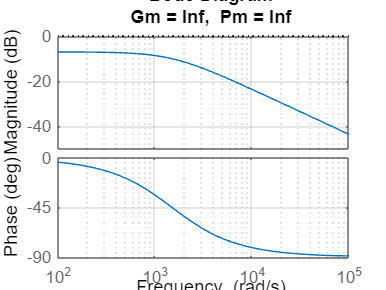

margin(dif)
grid on


pid=tf([Kp (Ki+Kp*wf+Kd*wf) Ki*wf],[1 wf 0])

pid =
 
  2700 s^2 + 5.88e06 s + 2.744e09
  -------------------------------
           s^2 + 1500 s
 
Continuous-time transfer function.





w=pid*obj

w =
 
  2700 s^2 + 5.88e06 s + 2.744e09
  -------------------------------
          s^3 + 1500 s^2
 
Continuous-time transfer function.



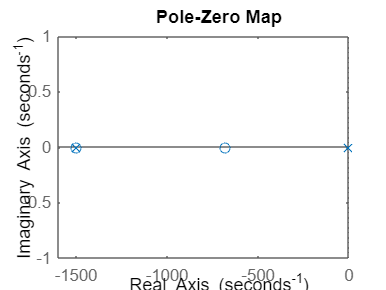

pzmap(w)

f=minreal(ss(w/(1+w)))

3 states removed.

f =
 
  A = 
           x1      x2      x3
   x1   -1001  -741.5  -564.8
   x2    6005   -2524    1978
   x3   -1351    1373  -675.2
 
  B = 
           u1
   x1   35.69
   x2  -48.73
   x3   16.63
 
  C = 
           x1      x2      x3
   y1   57.42  -5.135   24.08
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



f=tf(f)

f =
 
     2700 s^2 + 5.88e06 s + 2.744e09
  -------------------------------------
  s^3 + 4200 s^2 + 5.88e06 s + 2.744e09
 
Continuous-time transfer function.



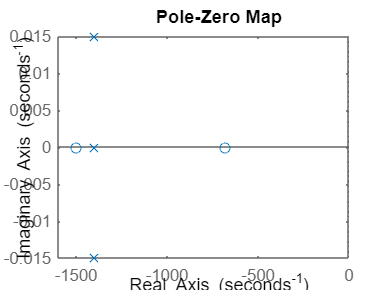

pzmap(f)

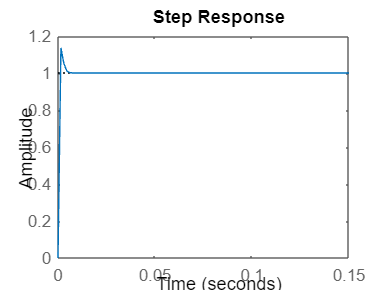

step(f,0.15)


piddis=c2d(pid,1/50e3)

piddis =
 
  2700 z^2 - 5284 z + 2585
  ------------------------
   z^2 - 1.97 z + 0.9704
 
Sample time: 2e-05 seconds
Discrete-time transfer function.



syms Kp Kd Ki s wf
PI=(Kp*s+Ki)/(s)

$$PI = \frac{\mathrm{Ki}+\mathrm{Kp}\,s}{s}$$

Ob=1/s

$$Ob = \frac{1}{s}$$

W=PI*Ob

$$W = \frac{\mathrm{Ki}+\mathrm{Kp}\,s}{s^{2}}$$

g=simplify(W/(1+W))

$$g = \frac{\mathrm{Ki}+\mathrm{Kp}\,s}{s^{2}+\mathrm{Kp}\,s+\mathrm{Ki}}$$

g=collect(g,s)

$$g = \frac{\mathrm{Kp}\,s+\mathrm{Ki}}{s^{2}+\mathrm{Kp}\,s+\mathrm{Ki}}$$

zel=(s+850)^2 % 10 Hz

$$zel = {\left(s+850\right)}^{2}$$

zel=collect(zel,s)

$$zel = s^{2}+1700\,s+722500$$


kp= 1.7e3

kp = 1700

ki= 0.7225e6

ki = 722500

pi2=tf([kp ki],[1 0])

pi2 =
 
  1700 s + 722500
  ---------------
         s
 
Continuous-time transfer function.



w=pi2*obj

w =
 
  1700 s + 722500
  ---------------
        s^2
 
Continuous-time transfer function.



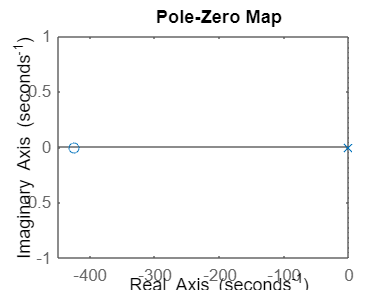

pzmap(w)

f=minreal(ss(w/(1+w)))

2 states removed.

f =
 
  A = 
           x1      x2
   x1   -1700  -705.6
   x2    1024       0
 
  B = 
       u1
   x1  64
   x2   0
 
  C = 
          x1     x2
   y1  26.56  11.02
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



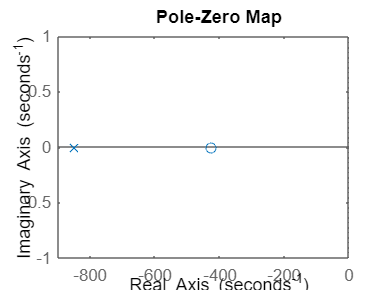

pzmap(f)

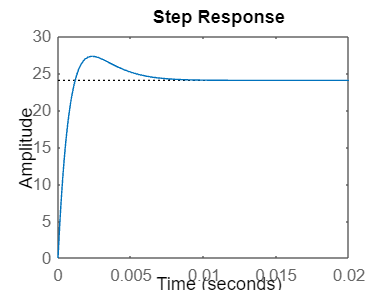

step(24*f,0.02)